# Exercici 8 de Laboratori

## Classificació de caràcters

(Per Francesc Forn, Raúl Lumbreras i Martí Vall)

## Introducció

Obrim la imatge i binaritzem amb un llindar fix:

I = rgb2gray(imread('Joc_de_caracters.jpg'));
BI = I < 128; % lletres estan en negre

Obtenim la llista dels píxels que conformen cadascun dels caràcters segmentats:

CC = bwconncomp(BI);

Mesurem algunes propietats descriptores de forma (fortament dependents de la mida de l’objecte):

props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength','Circularity','Perimeter','Solidity','EulerNumber','Centroid'); %afegir-ne més

Cal passar de llista a taula, per això construïm una taula de mesures o taula d’observacions:

%C = props.Centroid
%Cx = C(:,1);
%Cy = C(:,2);
X = [ props.MajorAxisLength; props.MinorAxisLength;props.Circularity; props.Solidity; props.EulerNumber;]';

Construïm el output o resultat que voldríem obtenir a partir de les entrades X (taula de mesures):

OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' 'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};

Construcció d'un classificador. Sense entrar en detalls, ni consideracions d’overfiting, farem servir un model/funció de classificació anomenada *TreeBagger* que ens retorna una variable anomenada *Classifier*, variable que una posterior funció de predicció farà servir per predir el resultat de noves observacions. El vector OUT és el resultat que el *TreeBagger* haurà d’aprendre a “endevinar” a partir de les observacions X.

Classifier = TreeBagger(100,X,OUT');

Ara cal comprovar que tan bo és el classificador, repetint el procediment de mesura amb una nova imatge de test.

I = rgb2gray(imread('Joc_de_caracters_deformats.jpg'));
BI = I < 128; % separem el background
figure;imshow(BI);

CC = bwconncomp(BI);
props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength','Circularity','Perimeter','Solidity','EulerNumber','Centroid');
%C = props.Centroid
%Cx = C(:,1);
%Cy = C(:,2);
X = [ props.MajorAxisLength; props.MinorAxisLength; props.Circularity; props.Solidity; props.EulerNumber;]'; 

Amb la variable *Classifier* i la funció *Predict* intentem endevinar quin caràcter és cadascun (*label*) i quina puntuació té la classificació (*score*).

[label,score] = predict(Classifier,X);
% mostrem el resultat mes probable i la seva puntuació (score)
table(Classifier.ClassNames,label,max(score,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.66 
    {'1'}    {'1'}    0.52 
    {'2'}    {'2'}    0.31 
    {'3'}    {'5'}    0.19 
    {'4'}    {'4'}    0.59 
    {'5'}    {'5'}    0.35 
    {'6'}    {'6'}    0.63 
    {'7'}    {'7'}    0.69 
    {'8'}    {'8'}    0.48 
    {'9'}    {'9'}    0.72 
    {'B'}    {'B'}     0.6 
    {'C'}    {'C'}    0.45 
    {'D'}    {'D'}    0.67 
    {'F'}    {'F'}    0.68 
    {'G'}    {'G'}    0.56 
    {'H'}    {'H'}    0.65 


Analitzeu quines observacions/característiques són més les més influents per classificar les lletres. També podeu comparar resultats utilitzant altres classificadors.

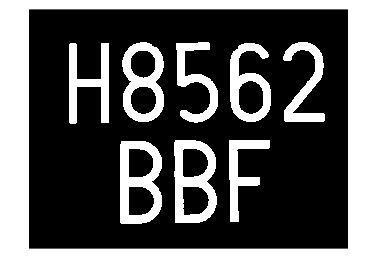

I = rgb2gray(imread('matricula.jpeg'));
BI = I < 100; % separem el background
SE = strel("disk",7);
BI = imopen(BI,SE);

OUT = {'H' '8' '5' '6' '2' 'B' 'B' 'F'};

figure;imshow(BI);

CC = bwconncomp(BI);
props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength','Circularity','Perimeter','Solidity','EulerNumber','Centroid');
%C = props.Centroid
%Cx = C(:,1);
%Cy = C(:,2);
X = [ props.MajorAxisLength; props.MinorAxisLength; props.Circularity; props.Solidity; props.EulerNumber;]'; 

[label,score] = predict(Classifier,X);
% mostrem el resultat mes probable i la seva puntuació (score)
table(OUT',label,max(score,[],2),'VariableNames',{'Name','Label','Score'})

ans = 8×3 table
    Name     Label    Score
    _____    _____    _____

    {'H'}    {'Z'}    0.19 
    {'8'}    {'B'}    0.17 
    {'5'}    {'B'}    0.17 
    {'6'}    {'B'}    0.17 
    {'2'}    {'Z'}    0.24 
    {'B'}    {'H'}    0.17 
    {'B'}    {'H'}    0.17 
    {'F'}    {'Z'}    0.22 
